start = tic;
addpath functions\
addpath rawData\
latex_interpreter

systemName = 'ieee123'

systemName = 'ieee123'

numAreas = 4

numAreas = 4


N = max(actualBusNums);

loss_min = true;   % CVR  = 0, Loss minimization = 1;
itrMax = 150; %Max no. of permissible iterations for optimizing an area
% Stopping Criterion:
eps = 0.001 ; % Tolerance
displayTables = false;
displayNetworkGraphs = true;
displayActualBusNumbersInGraphs = false;
savePlots = true;
CVR = [0; 0]; %as opposed to [0.6; 3.0]

load_mult = 1;
gen_mult = 1;

kVA_B = 1000;                                        % base kVA
kV_B = 4.16/sqrt(3);  

systemDataFolder = strcat("rawData/", systemName, "/numAreas_", num2str(numAreas), "/");
connectionBusesFilename = strcat(systemDataFolder, "connectionBuses.txt");
CBTable = readtable(connectionBusesFilename);
CBMatrix = table2array(CBTable);

connectionBuses_FullFilename = strcat(systemDataFolder, "connectionBuses_Full.txt");
CB_FullTable = readtable(connectionBuses_FullFilename)

CB_FullTable = 3×6 table
    parentArea    childArea    connectingBus_parentArea_parentIdx    connectingBus_childArea_parentIdx    connectingBus_parentArea_childIdx    connectingBus_childArea_childIdx
    __________    _________    __________________________________    _________________________________    _________________________________    ________________________________

        1             2                        15                                   40                                    1                                   2                
        1             3                        20                                   41                                    1                                   2                
        2             4                        11                 

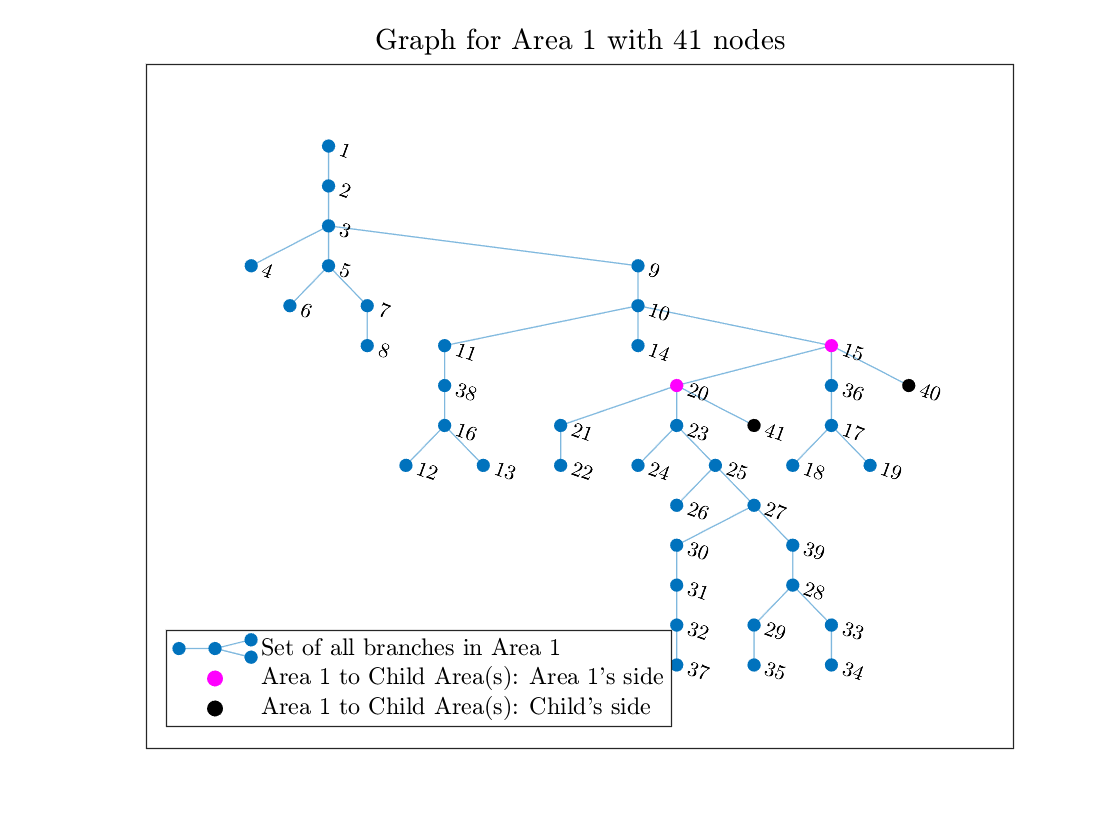

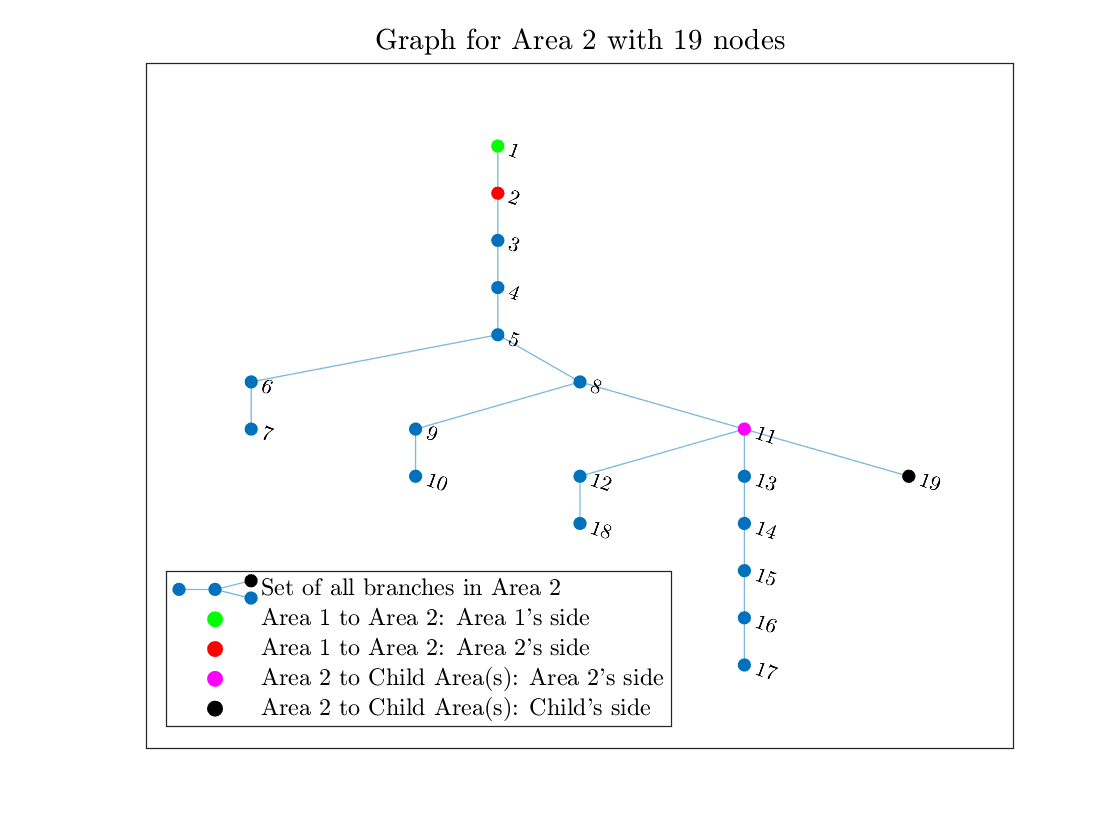

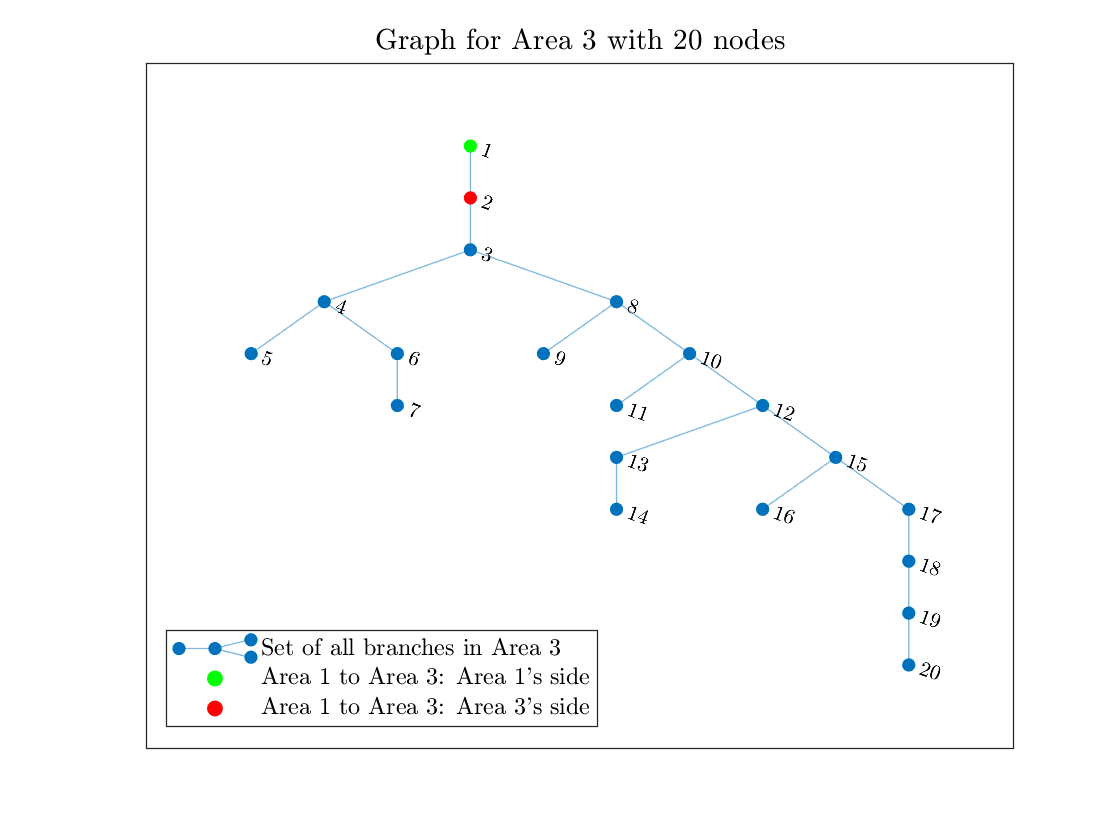

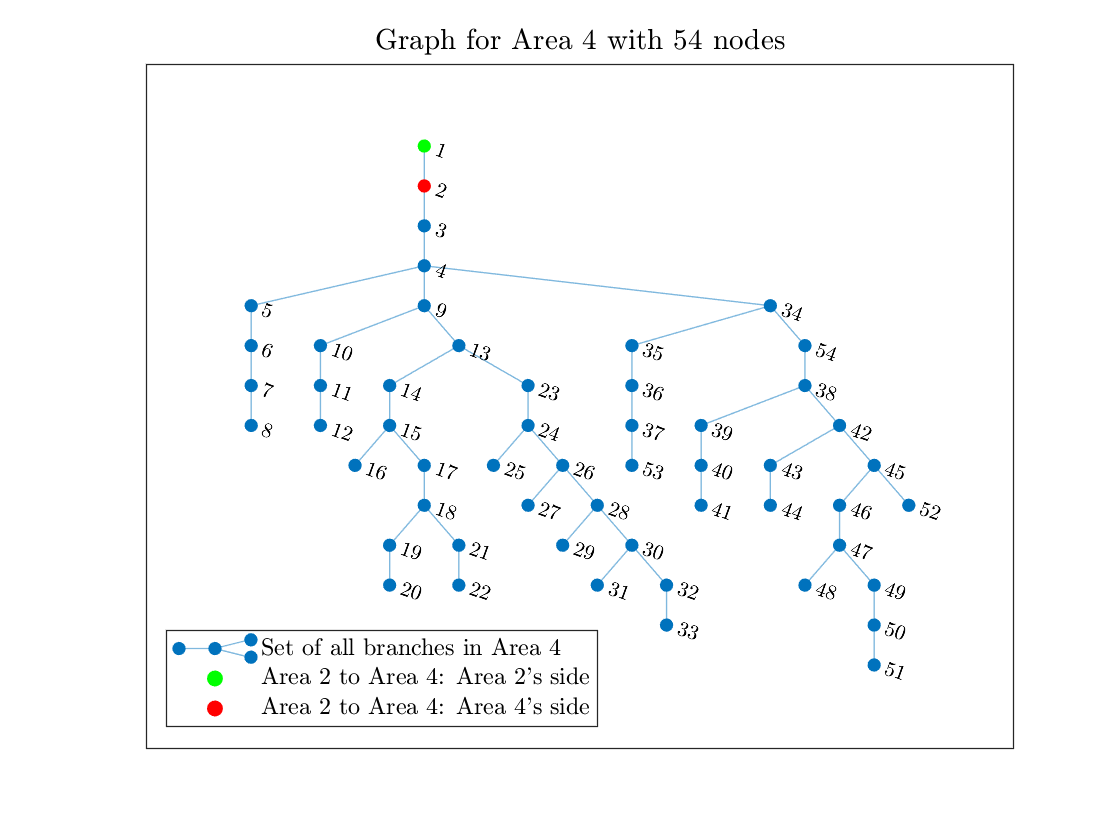


% numAreas = max(max(CBTable.parentArea, CBTable.childArea));

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
isLeaf = ones(numAreas, 1);
isRoot = ones(numAreas, 1);

for relationshipNum = 1:numRelationships
    parentArea = CBTable.parentArea(relationshipNum);
    isLeaf(parentArea, 1) = 0;
    childArea = CBTable.childArea(relationshipNum);
    isRoot(childArea, 1) = 0;
    numChildAreas(parentArea) = numChildAreas(parentArea) + 1; %contains which area has how many children
end

maxConnectingBusNum = max(CBTable.connectingBus);
S_allRelationships = zeros(length(CBTable.parentArea), 1);

S_parent = zeros(numAreas, 1);
S_child = zeros(N, numAreas);
v2_parent = 1.03^2*ones(numAreas, 1);
v2 = zeros(N, numAreas);
decisionVars = zeros(N, numAreas);
% Loop:

keepRunningIterations = 1;
itr = 0;
time_dist = zeros(itrMax, numAreas);
microIterationLosses = zeros(itrMax, numAreas);

%
while keepRunningIterations
    % Solve Areas parallelly:
    for Area = 1:numAreas

        v2_parent_Area = v2_parent(Area);
        S_childAreas = S_allRelationships(CBTable.parentArea == Area);
        isLeaf_Area = isLeaf(Area);
        isRoot_Area = isRoot(Area);
        numChildAreas_Area = numChildAreas(Area);

        [v2_Area, S_parent_Area, S_child_Area, ...
            microIterationLosses, decisionVars_Area, ...
            time_dist, R, T_Area, N_Area, busDataTable_Area, branchDataTable_Area] = ...
            NL_OPF_dist(v2_parent_Area, ...
            S_childAreas, ...
            Area, isLeaf_Area, isRoot_Area, numChildAreas_Area, N, CVR, ...
            kV_B, kVA_B, load_mult, gen_mult, numAreas, ...
            systemDataFolder, ...
            microIterationLosses, time_dist, itr, ...
            CBTable, CB_FullTable, displayTables, displayNetworkGraphs, ...
            displayActualBusNumbersInGraphs, savePlots);
        
        S_parent(Area) = S_parent_Area;
        lenv2_Area = size(v2_Area, 1);
        lenv2 = size(v2, 1);
        if lenv2_Area < lenv2
            v2_Area = [v2_Area; zeros(lenv2 - lenv2_Area, 1)];
            decisionVars_Area = [decisionVars_Area; zeros(lenv2 - lenv2_Area, 1)];
            lenDec_Var = size(decisionVars, 1);
            if lenv2 > lenDec_Var
                decisionVars = [decisionVars; zeros(lenv2 - lenDec_Var, numAreas)];
            end      
        elseif lenv2_Area > lenv2
            v2 = [v2; zeros(lenv2_Area - lenv2, numAreas)];
            lenDec_Var = size(decisionVars, 1);
            if lenv2_Area > lenDec_Var
                decisionVars = [decisionVars; zeros(lenv2_Area - lenDec_Var, numAreas)];
            end
        end
        
        if size(S_child_Area, 1) < size (S_child, 1)  % Ensuring the dimensions will match to store the S flow
            S_child_Area(end+1:size(S_child,1)) = 0;
            
        elseif size(S_child_Area, 1) > size (S_child, 1)
            S_child(end+1:size(S_child_Area,1),:) = 0;
        end
        
        decisionVars(:, Area) = decisionVars_Area;
        v2(:, Area) = v2_Area;   % Storing all the square of the node voltages
        S_child(:, Area) = S_child_Area;   % Storing all the S flow of the Area
        
%         disp('*************')
%         disp(['Iteration: ', num2str(itr), '    Area: ', num2str(Area)])
    end
    
    
    % Residual Matrix:
    keepRunningIterations = 0;
    R_max = zeros(itrMax, 1);
    for relationshipNum = 1:size(CBMatrix, 1)
        R = [
            (S_child((CBMatrix(relationshipNum,3)-1),CBMatrix(relationshipNum,1))) - (S_parent(CBMatrix(relationshipNum,2)));
            v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) - v2_parent(CBMatrix(relationshipNum,2))];        
        if max(abs(R)) > R_max(itr+1)
            R_max(itr+1) = max(abs(R));
        end
    end
    if R_max(itr+1) > eps  % Checking if any boundary converged or not.
        keepRunningIterations = 1;
        a(1) = 0.25;
        a(2) = 0.05;
        %Communication-
        for relationshipNum = 1:size(CBMatrix,1)
            V_iter(itr+1,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) = v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) ;
            Se_iter(itr+1,CBMatrix(relationshipNum,2)) = S_parent(CBMatrix(relationshipNum,2));
            
            if itr>2
                v2_parent(CBMatrix(relationshipNum,2)) = a(2)*V_iter(itr-1,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1))+...
                    a(1)*V_iter(itr,CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1))+...
                    (1-sum(a))*v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1)) ;
                
                S_allRelationships(relationshipNum, 1) = a(2)*Se_iter(itr-1,CBMatrix(relationshipNum,2))+...
                    a(1)*Se_iter(itr,CBMatrix(relationshipNum,2))+...
                    (1-sum(a))*S_parent(CBMatrix(relationshipNum,2));
            else
                v2_parent(CBMatrix(relationshipNum,2)) = v2(CBMatrix(relationshipNum,3),CBMatrix(relationshipNum,1));
                S_allRelationships(relationshipNum, 1) = S_parent(CBMatrix(relationshipNum,2));
            end
        end
        itr = itr + 1;
    end
    if itr> itrMax
        keepRunningIterations = 0;
    end
    
end


disp('00000000000000')

00000000000000


V_node_sq = v2_parent(1);
Dec_Var_overall = 0;
for j = 1:numAreas
    v_area1 = v2(2:min(CBMatrix((find(j==CBMatrix(:,1))),3))-1,j);
    DV_area1 = decisionVars(2:min(CBMatrix((find(j==CBMatrix(:,1))),3))-1,j);
    
    if (isLeaf(j))
        end_node = min(find(v2(:,j)==0));
        if (end_node)
            v_area1 = v2(2:end_node-1,j);
            DV_area1 = decisionVars(2:end_node-1,j);
            
            disp('---')
        else
            v_area1 = v2(2:end,j);
            DV_area1 = decisionVars(2:end,j);
            disp('%%%%%%')
        end
    end
    node_size(j)= size(v_area1,1);
    V_node_sq = [V_node_sq;v_area1];
    Dec_Var_overall = [Dec_Var_overall;DV_area1 ];
    
    
end

---
---



for j = 1:length(actualBusNums)
    V_node_sq_1(actualBusNums(j),1) = V_node_sq(j);
    Dec_Var_overall_1(actualBusNums(j),1) = Dec_Var_overall(j);
end
%
v1 = (sqrt(V_node_sq_1))';
decisionVars = Dec_Var_overall_1';

microIterationLosses = microIterationLosses(1:itr, :);
dist_time = microIterationLosses(1:itr, :);

disp('------------------------------------------------------------')

------------------------------------------------------------


% if loss_min
disp(['Line Loss: ', num2str(sum(microIterationLosses(end, :)*1000)),' kW'])                       

Line Loss: 12.1761 kW


disp(['Substation Power: ', num2str(real(S_child(1))*1000),' kW']) 

Substation Power: 768.2385 kW


% end
disp(['Time to Solve: ', num2str(max(sum(time_dist))), 'sec'])

Time to Solve: 8.8906sec


disp('------------------------------------------------------------')

------------------------------------------------------------



elapsed = toc(start)

elapsed = 15.6113